% Initialize the boids' positions and velocities
num_boids = 50;
limit = 10;
all_boids = limit.*rand(num_boids, 2) % Random positions between [0, 1]

all_boids =     4.9547    4.4090
    6.0919    8.7576
    0.0481    8.6495
    5.8773    3.5515
    7.7746    6.3115
    6.5718    8.6455
    5.2831    0.2099
    8.2577    0.7682
    9.6243    3.7671
    3.1374    1.4919



tic
g = get_weighted_adjacency_matrix(all_boids, 1)

g =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4475         0         0         0         0         0         0         0
         0         0         0         0         0    0.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

toc

Elapsed time is 0.020286 seconds.


s = sparse(g)

s =   (43,1)       0.4475
   (6,2)       0.4929
  (17,3)       0.1697
  (21,4)       0.9387
  (35,4)       0.2592
   (2,6)       0.4929
  (27,7)       0.6727
  (11,8)       0.5146
  (24,8)       0.9404
  (25,9)       0.7940
  (26,9)       0.8346
  (47,9)       0.5828
  (50,9)       0.9820
  (15,10)      0.2866
  (37,10)      0.7476
   (8,11)      0.5146
  (42,12)      0.7807
  (17,14)      0.9578
  (18,14)      0.9094
  (40,14)      0.0963
  (10,15)      0.2866
   (3,17)      0.1697
  (14,17)      0.9578
  (40,17)      0.9715
  (14,18)      0.9094
  (40,18)      0.9126
  (21,20)      0.8562
   (4,21)      0.9387
  (20,21)      0.8562
  (34,21)      0.7719
  (35,21)      0.8013
  (34,22)      0.5522
   (8,24)      0.9404
   (9,25)      0.7940
  (26,25)      0.5643
   (9,26)      0.8346
  (25,26)      0.5643
  (47,26)      0.9287
   (7,27)      0.6727
  (29,27)      0.8100
  (48,28)      0.9004
  (27,29)      0.8100
  (37,29)      0.7799
  (36,30)      0.5807
  (37,33)      0.7296
  (21,

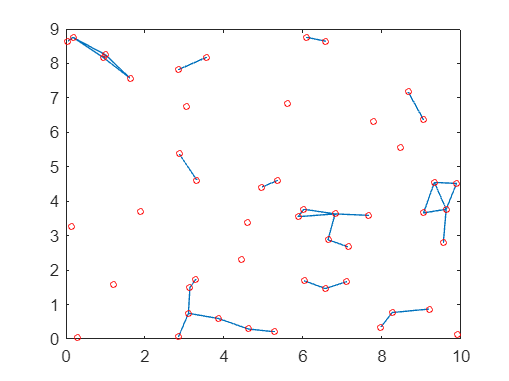

gplot(s,all_boids)
hold on
plot(all_boids(:,1), all_boids(:,2), 'ro', 'MarkerSize', 3.5)

sprank(s)

ans = 35

function out = get_unweighted_adjacency_matrix(points, range)
    
    function neighbors = findNeighbours(boids, all_boids, range)
    neighbors = rangesearch(all_boids, boids, range);
    neighbors = cellfun(@(a) a(2:end), neighbors, 'UniformOutput', false);
    end

    function out = cell2logic(c, n)
    out = zeros(1, n);
    out(c) = 1;
    end

    neighbours = findNeighbours(points, points, range);
    out = cell2mat(cellfun(@(a) cell2logic(a, size(points, 1)),  neighbours, 'UniformOutput', false));

end

function out = get_weighted_adjacency_matrix(points, range)

    distances = pdist2(points, points);
    out = get_unweighted_adjacency_matrix(points, range) .* distances;

end